# Vehicle Parameter

clear all
clc
clf("reset")
Mass=1400;
T_Radius=0.33;
Transmission_efficiency=0.95;
Rolling_resistance_coefficient=0.015;
Area_Frontal=1.6;
cd=0.28;
rho_air=1.22;
RPM=[1000 3000 8000];
Torque=[50 220 50];
Torque_Coeffiecient=polyfit(RPM,Torque,2);
ig=1;
final_reduction=4;


## create array for  the engine

RPM_engine=linspace(1000,8000,50);
Torque_engine=Torque_Coeffiecient(1).*RPM_engine.^2+Torque_Coeffiecient(2).*RPM_engine+Torque_Coeffiecient(3);

## plot torque and RPM

% yyaxis right;
% RPM_plot=plot(RPM_engine,Torque_engine);
% ylabel('Torque');
% RPM_plot.LineWidth=2;
% RPM_plot.Marker='none';
% RPM_plot.Color='r';
% hold on 

## get power engine

% yyaxis left;
% ylabel('Power');
% Power_engine=Torque_engine.*2*pi.*RPM_engine/60;
% p2=plot(RPM_engine,Power_engine,'g');
% hold off

fTR=@(v) Rolling_resistance_coefficient*Mass*9.8 +0.5*rho_air*cd*Area_Frontal*v.^2/3.6^2;
Speed=(2*pi*RPM_engine/60)*T_Radius/(ig*final_reduction);
TR=fTR(Speed);
PR=TR.*Speed;

## plot engine power and total resstance with forward speed


syms symNe symVx symTR

% create symbolic equation for tractive power in terms of forward speed

symTe = Torque_Coeffiecient(1)*symNe^2 + Torque_Coeffiecient(2)*symNe +Torque_Coeffiecient(3);

symPe = symTe * 2*pi*symNe/60;

symPw = symPe * Transmission_efficiency; % in terms of rpm

% vx = 2*pi*radius*Ne/60/ig/FinalReduction * 3.6
% Ne = vx * 60*ig*finalreduction/2/pi/radius/3.6
ig=1.59;

symPw = subs( symPw , symNe , symVx*60*ig*final_reduction/2/pi/T_Radius/3.6 ); % function of forward speed (km/h)

% find maximum speed >>> equate tractive power and reistive power

symPR = (Rolling_resistance_coefficient*Mass*9.8 + 0.5*rho_air*cd*Area_Frontal*(symVx/3.6)^2)*symVx/3.6; % symbolic equation of resistive power

solve( symPw == symPR , symVx )

$$ans = \left(\begin{array}{c} 0\\ -\frac{7704397954535254917120\,\pi \,\left(7260\,\sqrt{\frac{6895143718923860679614447854493}{615273220649185457681203200}-\frac{41812267\,\pi^{2}}{3608550}}-907307\right)}{655247949163741589798912\,\pi^{2}+249483819751907492935546875}\\ \frac{7704397954535254917120\,\pi \,\left(7260\,\sqrt{\frac{6895143718923860679614447854493}{615273220649185457681203200}-\frac{41812267\,\pi^{2}}{3608550}}+907307\right)}{655247949163741589798912\,\pi^{2}+249483819751907492935546875} \end{array}\right)$$


%fplot( [symPw , symPR] , [0 260] )

% create anonymous function for tracive effor with gearbox reduction ratio
% as an input

fFx = @(igs) subs( symTe*igs*final_reduction*Transmission_efficiency/T_Radius , symNe ,...
symVx*60*igs*final_reduction/2/pi/T_Radius/3.6 );
fFx_ms = @(igs) subs( symTe*igs*final_reduction*Transmission_efficiency/T_Radius , symNe ,...
symVx*60*igs*final_reduction/2/pi/T_Radius );
symFX=fFx_ms(ig)

$$symFX = -\frac{79834822320610397739375\,{\mathrm{symVx}}^{2}}{767269261315856662528\,\pi^{2}}+\frac{24497289\,\mathrm{symVx}}{15125\,\pi }-\frac{86602}{55}$$

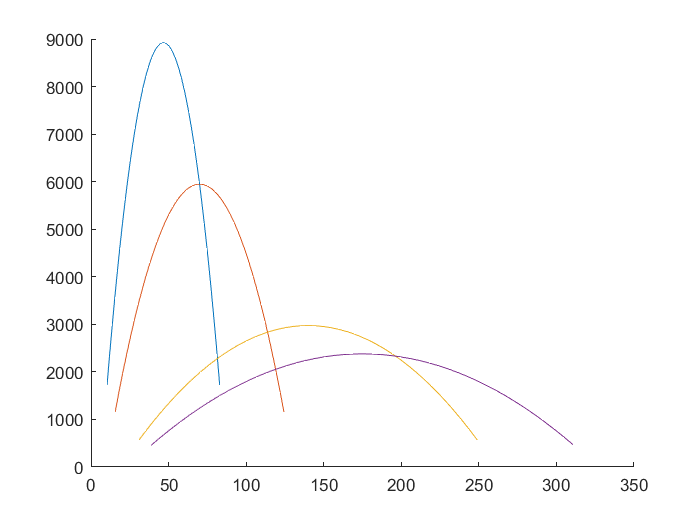


fFX_speed= @(v) subs( symTe*ig*final_reduction*Transmission_efficiency/T_Radius , symNe ,...
v*60*ig*final_reduction/2/pi/T_Radius/3.6 );
GBratios = [ 3 2 1 0.8];

 for i=1:4
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 hold on
 fplot( fFx(GBratios(i)) , 2*pi*T_Radius/60/GBratios(i)/final_reduction*3.6*[ 1000 8000 ] )
 end
 hold off



my_speed=[105:0.05:120];
tractive=double(fFX_speed(my_speed));
Total_R=fTR(my_speed);
acc_inverse=Mass./(tractive-Total_R);
time=0;
[~,X]=size(my_speed)

X = 301

for i=1:X-1
    extra_t=(my_speed(i+1)-my_speed(i))*(acc_inverse(i)+acc_inverse(i+1))/2/3.6;
    time=time+extra_t;
    time_arr(i)=time;
end


## solve by integration

symTR=Rolling_resistance_coefficient*Mass*9.8 +0.5*rho_air*cd*Area_Frontal*symVx^2;
syminv_acc=Mass/(symFX-symTR)

$$syminv\_acc = -\frac{1400}{\frac{854\,{\mathrm{symVx}}^{2}}{3125}-\frac{24497289\,\mathrm{symVx}}{15125\,\pi }+\frac{79834822320610397739375\,{\mathrm{symVx}}^{2}}{767269261315856662528\,\pi^{2}}+\frac{97921}{55}}$$

accurate_t=double(int(syminv_acc,105/3.6,120/3.6))

accurate_t = 1.5586

## calculate distance

acc_distance=double(int(symVx*syminv_acc,105/3.6,120/3.6))

acc_distance = 48.8049



GB_ratios=[2.26;1.9;1.59;1.33;1.12;0.94];
[XR,~]=size(GB_ratios)

XR = 6

upspeed_shift_speed=zeros(1,length(GB_ratios)-1);
for nig=2:6
    solv_speed=vpasolve(fFx_ms(GB_ratios(nig-1))==fFx_ms(GB_ratios(nig)),symVx);
    upspeed_shift_speed(nig-1)=max(solv_speed);
end
